# Quickstart: Accessing Two-Photon Calcium Imaging Data from the Allen Brain Observatory

This short example demonstrates the basics of exploring and examining items within the Visual Coding 2P dataset [1] from the Allen Brain Observatory [2].

### View and Filter Visual Coding 2P Dataset Items 

#### View Available Items

Use a `bot.list()` function to obtain a listing of all available experimental ***session*** items: 

availSessions = bot.listSessions('ophys'); % specify 'ophys' to indicate the Visual Coding 2P dataset

Similar functions exist for other dataset item types: `bot.listCells() & bot.listExperiments().`

The `bot.list()` functions return [**table** objects](https://www.mathworks.com/help/matlab/tables.html) containing identifiers and other columns of information about the available items: 

availSessions % simplified command equivalent to disp(availSessions)

availSessions = 2684×14 table
       id        experiment_container_id     stimulus_name     targeted_structure_acronym    fail_eye_tracking    imaging_depth        cre_line        date_of_acquisition                     name                     specimen_id    experiment_container     specimen     targeted_structure    well_known_files
    _________    _______________________    _______________    __________________________    _________________    _____________    ________________    ____________________    _____________________________________    ___________    _______________

There are thousands of sessions in this dataset. The displayed table can be scrolled horizontally & vertically in the Live Editor to explore information about each. 

#### Filter Items by Criteria

Item tables can be filtered to focus on those meeting particular criteria of interest, by using [**tabular indexing**](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html) operations: 

% select experiments from the most orientation/direction-selective areas of visual cortex 
filteredSessions = availSessions(ismember(availSessions.targeted_structure_acronym, categorical(["VISal" "VISrl" "VISam"])), :);

% select experiments with GCaMP6f expression enriched in Layer 2/3 and Layer 4 of cortex
filteredSessions = filteredSessions(filteredSessions.cre_line == "Cux2-CreERT2", :);

% select experiments imaging from the shallowest depth in Layer 2/3
filteredSessions = filteredSessions(filteredSessions.imaging_depth == 175,:);

% select experiments with eye tracking data available
filteredSessions = filteredSessions(~filteredSessions.fail_eye_tracking, :);

% select experiments with drifting grating and natural movie stimuli
filteredSessions = filteredSessions(filteredSessions.stimulus_name == "three_session_A", :);
disp(filteredSessions)

       id        experiment_container_id     stimulus_name     targeted_structure_acronym    fail_eye_tracking    imaging_depth       cre_line       date_of_acquisition                       name                      specimen_id    experiment_container     specimen     targeted_structure    well_known_files
    _________    _______________________    _______________    __________________________    _________________    _____________    ______________    ____________________    ________________________________________    ___________    ____________________    __

### Examine Session Items

#### Obtain Session of Interest

From the table of filtered items, one or more specific items can be obtained for further examination using the `bot.get() `functions`: `

sessionUnderStudy = bot.getSessions(filteredSessions(1,:)); 
sessionUnderStudy.info    

ans = struct with fields:
                            id: 503412730
       experiment_container_id: 511510695
                 stimulus_name: three_session_A
    targeted_structure_acronym: VISal
             fail_eye_tracking: 0
                 imaging_depth: 175
                      cre_line: "Cux2-CreERT2"
           date_of_acquisition: 23-Feb-2016 19:10:20
                          name: "20160223_222425_3StimA"
                   specimen_id: 495727000
          experiment_container: [1×1 struct]
                      specimen: [1×1 struct]
            targeted_structure: [1×1 struct]
              well_known_files: [3×1 struct]


These `info` structure fields reflect the information from the session item's corresponding row in the filtered table above.

#### Examine Session of Interest

The session of interest can be examined more closely by displaying the obtained session item: 

disp(sessionUnderStudy)

  OphysSession with properties:

                                   info: [1×1 struct]
                                     id: 503412730
                           session_type: three_session_A
                            linkedFiles: [2×1 table]

   Linked Items
                             experiment: [1×1 bot.item.Experiment]
                                  cells: [3×94 table]

   Linked File Values ('SessNWB')
                      cell_specimen_ids: '[on demand]'
          corrected_fluorescence_traces: '[on demand]'
                fluorescence_timestamps: '[on demand]'
                    fluorescence_traces: '[on demand]'
            fluorescence_traces_demixed: '[on demand]'
                fluorescence_traces_dff: '[on demand]'
                         max_projection: '[on demand]'
                      motion_correction: '[on demand]'
                             neuropil_r: '[on demand

The displayed session item is an [**object**](https://www.mathworks.com/help/matlab/matlab_oop/create-a-simple-class.html) with has numerous additional [**properties**](https://www.mathworks.com/help/matlab/matlab_oop/create-a-simple-class.html#buoz2sc), allowing the session of interest to be examined more closely. 

### View and Plot Neural Activity in Detected Cells

For the Visual Coding 2P dataset, neural recordings were obtained from the visual cortex in the form of two-photon fluoresence. These are reflected in the varioius `fluorescence `properties: 

traces = sessionUnderStudy.fluorescence_traces_dff;
tall(traces) % display as a tall array 

ans =

  115,744×119 tall single matrix

  Columns 1 through 18

    0.1638    0.0245    0.1740    0.0660    0.0750    0.0769    0.1267    0.1671    0.1499    0.1691    0.2176    0.1915    0.0806    0.2626    0.1452    0.1646    0.0906    0.0778
    0.0714    0.0855    0.1475    0.0654    0.0603    0.1083    0.0498    0.0936    0.1107    0.1507    0.1345    0.1417    0.0896    0.2035    0.1483    0.0872    0.0930    0.1670
    0.0800    0.1205    0.0862    0.1093    0.1051    0.1013   -0.0124    0.1221    0.1098    0.1899    0.1285    0.1507    0.0636    0.1928    0.1793    0.0920    0.0837    0.2201
         0    0.0388    0.0638    0.1126    0.1018    0.1010    0.0940    0.1055    0.0513    0.2137    0.0959    0.0371    0.0853    0.1686    0.0995    0.1090    0.1954    0.0984
    0.0957    0.0294    0.0696    0.0521    0.1168    0.1441    0.1358    0.1015    0.0

Here the `fluorescence_traces_dff `property is displayed as a [**tall array**](https://www.mathworks.com/help/matlab/tall-arrays.html) making its contents easier to understand at a glance. It contains 100K+ rows (timepoints)  across a much smaller number (100+) of columns. The columns represent **cells **(putative neurons) which were detected by the originators of the Visual Coding 2P dataset. 

The corresponding timepoints are also provided in another session property: 

timestamps = sessionUnderStudy.fluorescence_timestamps;
size(timestamps)

ans =       115744           1


The number of timestamps equals the height of the fluorescence traces above.

With the timepoints and fluorescence traces from the computationally detected cells, a sampling of putative neural recordings can be plotted: 

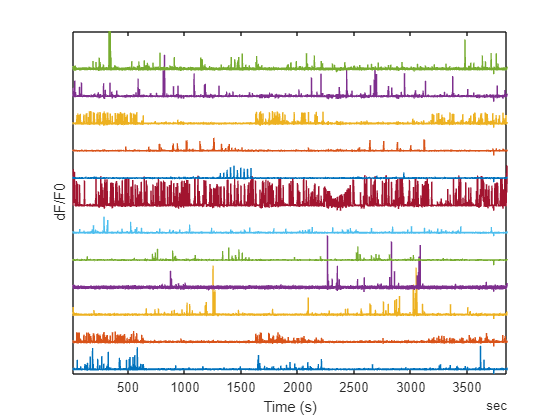

plot(timestamps, traces(:, 1:10:end) + (1:10:size(traces, 2))/3)
axis tight; xlabel('Time (s)'); set(gca, 'YTick', []); ylabel('dF/F0');

These putative cells differ considerably in the rates and patterns of peaks in their traces. This suggests there are a range of neural cell types and response types to the visual stimuli during the session. 

### Learn More

For an example of more in-depth neural data analysis of the Visual Coding 2P dataset using the Brain Observatory Toolbox, see the [**Ophys Demo**](matlab:open('./demos\OphysDemo.mlx')).

For more detailed guidance on how to use the Brain Observatory Toolbox with the Visual Coding 2P dataset, see the [**Ophys Tutorial**](matlab:open('./tutorials\OphysTutorial.mlx')).

### References

[1] Copyright 2016 Allen Institute for Brain Science. Visual Coding 2P dataset. Available from: [http://portal.brain-map.org/explore/circuits/visual-coding-2p](http://portal.brain-map.org/explore/circuits/visual-coding-2p).

[2] Copyright 2016 Allen Institute for Brain Science. Allen Brain Observatory. Available from: [portal.brain-map.org/explore/circuits](http://portal.brain-map.org/explore/circuits). 